op = bemoptions( 'sim', 'ret', 'interp', 'curve');
epstab = {epsconst(1), epstable('Ag.csv'), epsconst(5)};

diameter = 100;
p1 = comparticle( epstab, { trisphere( 144, diameter ) }, [ 2, 1 ], 1, op );
p2 = comparticle( epstab, { trisphere( 144, diameter ) }, [ 3, 1 ], 1, op );
inout = [2,1; 3,2; 3,1];  % Janus particle
% inout = [2,1; 1,2];     % Ag particle
% p3 = comparticle( epstab, janus_particle(pi/3, diameter), inout, [1 -2], [2 3], op);
p3 = comparticle( epstab, janus_particle(pi/3, diameter), inout, op);

trisphere: loading sphere529 from trisphere.mat


% p3 = rot(p3, -90, [1 0 0]);

bem1 = bemsolver( p1, op );
bem2 = bemsolver( p2, op );
bem3 = bemsolver( p3, op );

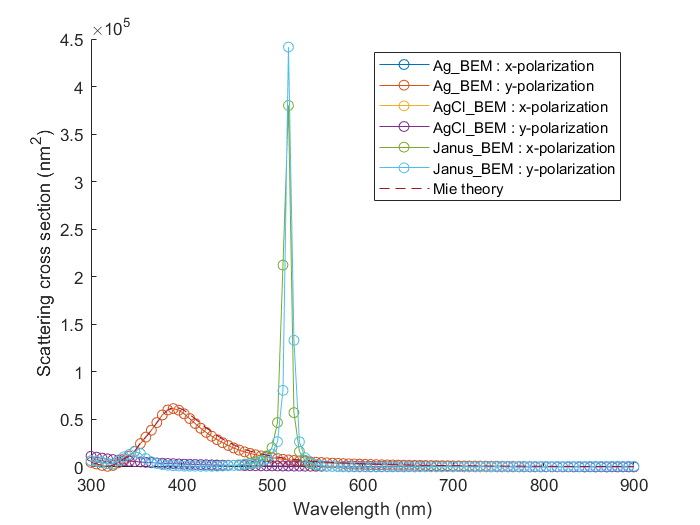


exc = planewave( [ 1, 0, 0; 0, 1, 0 ], [ 0, 0, 1; 0, 0, 1 ], op );
enei = linspace( 300, 900, 100 );
sca1 = zeros( length( enei ), 2 );
ext1 = zeros( length( enei ), 2 );
sca2 = sca1; sca3 = sca1;
ext2 = ext1; ext3 = ext1;

multiWaitbar( 'BEM solver', 0, 'Color', 'g', 'CanCancel', 'on' );
for ien = 1 : length( enei )
    sig1 = bem1 \ exc( p1, enei( ien ) );
    sig2 = bem2 \ exc( p2, enei( ien ) );
    sig3 = bem3 \ exc( p3, enei( ien ) );
    sca1( ien, : ) = exc.sca( sig1 );
    ext1( ien, : ) = exc.ext( sig1 );
    sca2( ien, : ) = exc.sca( sig2 );
    ext2( ien, : ) = exc.ext( sig2 );
    sca3( ien, : ) = exc.sca( sig3 );
    ext3( ien, : ) = exc.ext( sig3 );
    
    multiWaitbar( 'BEM solver', ien / numel( enei ) );
end
multiWaitbar( 'CloseAll' );

figure
hold on
plot( enei, sca1, 'o-'  );  hold on;
plot( enei, sca2, 'o-'  );  hold on;
plot( enei, sca3, 'o-'  );  hold on;

xlabel( 'Wavelength (nm)' );
ylabel( 'Scattering cross section (nm^2)' );

mie = miesolver( epstab{ 2 }, epstab{ 1 }, diameter, op );

plot( enei, mie.sca( enei ), '--' );  hold on

legend( 'Ag\_BEM : x-polarization', 'Ag\_BEM : y-polarization', ...
    'AgCl\_BEM : x-polarization', 'AgCl\_BEM : y-polarization', ...
    'Janus\_BEM : x-polarization', 'Janus\_BEM : y-polarization', ...
    'Mie theory' );

function p = janus_particle(theta_span, d)
    p0 = trisphere(512, d);
%     p0 = trispheresegment(linspace(0, 2*pi, 20), linspace(0, pi, 20), d);
%     p0 = p0.rot(-90, [1 0 0]);
    [p_outer, p_Ag] = select(p0, 'sphfun', @(phi, theta, r) theta < theta_span);
    p_inner = p_outer.flip(3);      
    p_inner = p_inner.shift([0, 0, min(p_outer.verts(:,3))-max(p_inner.verts(:,3))-1e-3]);
    p = {p_Ag, p_inner};
%     p = {p_inner, p_outer};
    p = {p_Ag, p_inner, p_outer};
end